close('all'); clear; clc;
setmadsympath();

mblue = [0 0.4470 0.7410];
morange = [0.8500 0.3250 0.0980];
myellow = [0.9290 0.6940 0.1250];
mpurple = [0.4940 0.1840 0.5560];
mgreen = [0.4660 0.6740 0.1880];
mcyan = [0.3010 0.7450 0.9330];
mred = [0.6350 0.0780 0.1840];

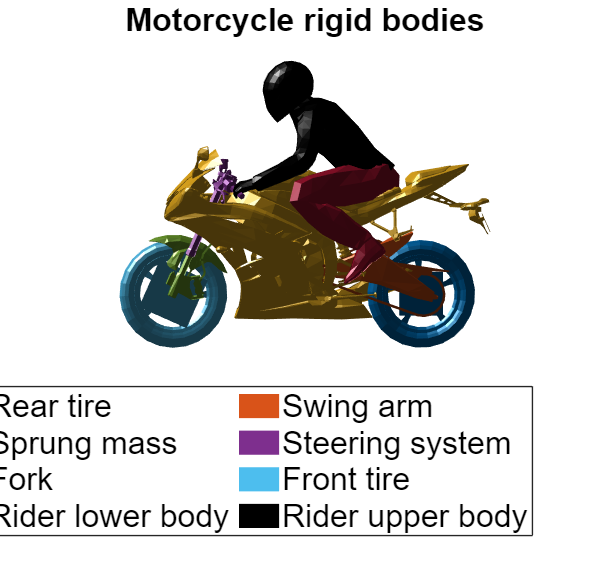

q = [0,0,0,0];

mf = bigSportsFigure();
mf.RearTire.Patch.FaceColor = mblue;
mf.SwingArm.Patch.FaceColor = morange;
mf.Base.Patch.FaceColor = myellow;
mf.Body.Patch.FaceColor = myellow;
mf.Handlebars.Patch.FaceColor = mpurple;
mf.ForkTop.Patch.FaceColor = mpurple;
mf.FrontFender.Patch.FaceColor = mgreen;
mf.Fork.Patch.FaceColor = mgreen;
mf.FrontTire.Patch.FaceColor = mcyan;
mf.LeftLeg.Patch.FaceColor = mred;
mf.RightLeg.Patch.FaceColor = mred;
mf.Driver.Patch.FaceColor = [0,0,0];
mf.LeftArm.Patch.FaceColor = [0,0,0];
mf.RightArm.Patch.FaceColor = [0,0,0];
setPose(mf,q);

fig = gcf;
axe = gca;
axis(axe,'equal');
axis(axe,'tight');
box(axe,'on');
light(axe);
view(180,0);
xticks(axe,[]);
yticks(axe,[]);
zticks(axe,[]);
axe.XColor = 'w';
axe.YColor = 'w';
axe.ZColor = 'w';

names = {
    'Rear tire';
    'Swing arm';
    'Sprung mass';
    '';
    'Steering system';
    '';
    'Fork';
    '';
    'Front tire';
    'Rider lower body';
    '';
    'Rider upper body';
    '';
    ''
    };

legend(axe,names{:}, ...
    'Fontsize', 24, ...
    'Orientation','horizontal', ...
    'Location','SouthOutside', ...
    'NumColumns',2 ...
    );

title(axe,'Motorcycle rigid bodies','FontSize',24);
fig.Position = [0,0,1080,1280];
zlim(axe,[0,1.6]);
print(fig,'motorcycle_rigid_bodies','-dpng','-r300');

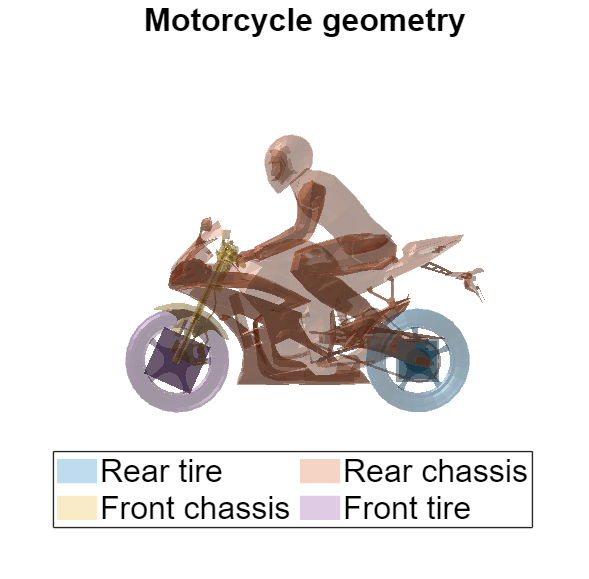

setColor(mf,mblue,morange,myellow,mpurple);
setAlpha(mf,0.25,0.25,0.25,0.25);

names = {
    'Rear tire';
    'Rear chassis';
    '';
    '';
    'Front chassis';
    '';
    '';
    '';
    'Front tire';
    '';
    '';
    '';
    '';
    ''
    };

legend(axe,names{:},'Fontsize',24);

title(axe,"Motorcycle geometry",'FontSize',24);

fig.Position = [0,0,1080,1280];
zlim(axe,[0,2]);
print(fig,'motorcycle_geometry','-dpng','-r300');

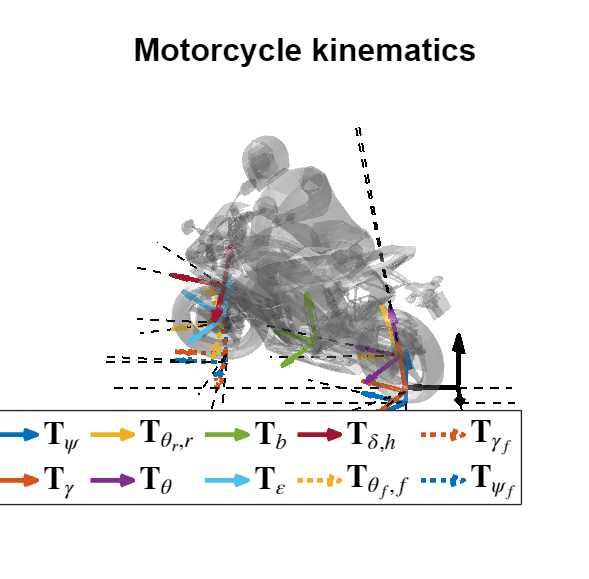

q = [-40,-15,1,30];
setPose(mf,q);

n0 = 0.75.*ones(1,3);

setColor(mf,n0,n0,n0,n0);
setAlpha(mf,0.25,0.25,0.25,0.25);

view(axe,180,15);
legend(axe,'off')
axis(axe,'tight')
camproj(axe,'perspective');

xhat = [1,0,0];
yhat = [0,1,0];
zhat = [0,0,1];

I = eye(3);
T = rigidtform3d(eye(3),[-0.3,-0.3,0]);
Lx1 = plotDoFLine(axe,T,yhat,1.3);
Lx2 = plotDoFLine(axe,rigidtform3d(I,[0,-0.3,0]),yhat,0.8);
Ly1 = plotDoFLine(axe,T,-xhat,0.3);
Ly2 = plotDoFLine(axe,rigidtform3d(I,[-0.3,0,0]),-xhat,0.3);
h = plotFrame(axe,T,[0,0,0]);

Ryaw = rotz(q(1));
Tyaw = rigidtform3d(Ryaw,[0,0,0]);
Lyaw1 = plotDoFLine(axe,rigidtform3d(I,[0,0,0]),xhat,0.7);
Lyaw2 = plotDoFLine(axe,Tyaw,xhat,0.7);
hyaw = plotFrame(axe,Tyaw,mblue);

Rcamber = Ryaw*rotx(q(2));
tr = 70E-03;
rr = 290E-03;
d = tr.*Ryaw(:,3);
Tcamber = rigidtform3d(Rcamber,d);
Lcamber1 = plotDoFLine(axe,rigidtform3d(Ryaw,d),yhat,0.5);
Lcamber2 = plotDoFLine(axe,rigidtform3d(Rcamber,d),yhat,0.5);
hcamber = plotFrame(axe,Tcamber,morange);

Rpitchr = Rcamber*roty(12);
d = tr.*Ryaw(:,3) + (rr - tr).*Rcamber(:,3);
Tpitchr = rigidtform3d(Rpitchr,d);
Lpitchr1 = plotDoFLine(axe,rigidtform3d(Rcamber,d),xhat,1);
Lpitchr2 = plotDoFLine(axe,rigidtform3d(Rpitchr,d),xhat,1);
hpitchr = plotFrame(axe,Tpitchr,myellow);

Rpitch = Rcamber*roty(q(3));
Tpitch = rigidtform3d(Rpitch,d);
Lpitch1 = plotDoFLine(axe,rigidtform3d(Rcamber,d),zhat,1.4);
Lpitch2 = plotDoFLine(axe,rigidtform3d(Rpitch,d),zhat,1.4);
hpitch = plotFrame(axe,Tpitch,mpurple);

caster = 24;
a = 749E-03;
an = 84.8E-03;
b = 572.9E-03;
e = 28.7E-03;
f = 234.4E-03;
h = 575E-03;

d = b.*Rpitch(:,1) + (h - rr).*Rpitch(:,3);
Tb = rigidtform3d(Rpitch,d);
hb = plotFrame(axe,Tb,mgreen);

Rcaster = Rpitch*roty(caster).';
d = b.*Rpitch(:,1) + a.*Rcaster(:,1);
Tcaster = rigidtform3d(Rcaster,d);
hcaster = plotFrame(axe,Tcaster,mcyan);

Rsteer = Rcaster*rotz(q(4));
d = d + e.*Rsteer(:,1) + f.*Rsteer(:,3);
Tsteer = rigidtform3d(Rsteer,d);
Lsteer1 = plotDoFLine(axe,rigidtform3d(Rcaster,d),xhat,0.5);
Lsteer2 = plotDoFLine(axe,rigidtform3d(Rsteer,d),xhat,0.5);
hsteer = plotFrame(axe,Tsteer,mred);

tf = 50E-03;
rf = 282E-03;

s = sind(caster);
c = cosd(caster);

lx = rf*s - an;
lz = -(rf*c^2 + (an - a)*s)/c;

R = Rsteer*roty(caster);
[yaw,camber,pitch] = dcm2angle(R.','ZXY');

Rpitchf = R*roty(rad2deg(pitch)).';
d = b.*Rpitch(:,1) + a.*Rcaster(:,1) - lz*Rsteer(:,3);

Tpitchf = rigidtform3d(Rpitchf*roty(12),d);
Lpitchf1 = plotDoFLine(axe,rigidtform3d(Rpitchf,d),xhat,0.5);
Lpitchf2 = plotDoFLine(axe,Tpitchf,xhat,0.5);
hpitchf = plotFrame(axe,Tpitchf,myellow,':');

Ryawf = Rpitchf*rotx(rad2deg(camber)).';
d = d - (rf - tf)*Rpitchf(:,3);
Tcamberf = rigidtform3d(Rpitchf,d);
Lcamberf1 = plotDoFLine(axe,rigidtform3d(Ryawf,d),yhat,0.8);
Lcamberf2 = plotDoFLine(axe,Tcamberf,yhat,0.6);
hcamberf = plotFrame(axe,Tcamberf,morange,':');

d = d - tf.*Ryawf(:,3);
Tyawf = rigidtform3d(Ryawf,d);
Lyawf1 = plotDoFLine(axe,rigidtform3d(eye(3),d),xhat,0.7);
Lyawf2 = plotDoFLine(axe,Tyawf,xhat,0.7);
Lxf1 = plotDoFLine(axe,rigidtform3d(eye(3),d),xhat,0.7);
Lxf2 = plotDoFLine(axe,rigidtform3d(eye(3),[-0.3,-0.3,0]),xhat,1.94);
Lyf1 = plotDoFLine(axe,rigidtform3d(eye(3),d),yhat,1.78);
Lyf2 = plotDoFLine(axe,rigidtform3d(eye(3),[-0.3,-0.3,0]),yhat,0.7);
hyawf = plotFrame(axe,Tyawf,mblue,':');

names = {
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '$\mathbf{T}_{\psi}$';
    '';
    '';
    '';
    '';
    '$\mathbf{T}_{\gamma}$';
    '';
    '';
    '';
    '';
    '$\mathbf{T}_{\theta_{r},r}$';
    '';
    '';
    '';
    '';
    '$\mathbf{T}_{\theta}$';
    '';
    '';
    '$\mathbf{T}_{b}$';
    '';
    '';
    '$\mathbf{T}_{\varepsilon}$';
    '';
    '';
    '';
    '';
    '$\mathbf{T}_{\delta,h}$';
    '';
    '';
    '';
    '';
    '$\mathbf{T}_{\theta_{f},f}$';
    '';
    '';
    '';
    '';
    '$\mathbf{T}_{\gamma_{f}}$';
    '';
    '';
    '';
    '';
    '';
    '';
    '$\mathbf{T}_{\psi_{f}}$';
    };

leg = legend(axe,names{:}, ...
    'Location','South', ...
    'FontSize',24, ...
    'NumColumns',5, ...
    'Interpreter','latex');

leg.IconColumnWidth = 32;

title(axe,"Motorcycle kinematics",'FontSize',24);

fig.Position = [0,0,1080,1350];
print(fig,'dof','-dpng','-r300');

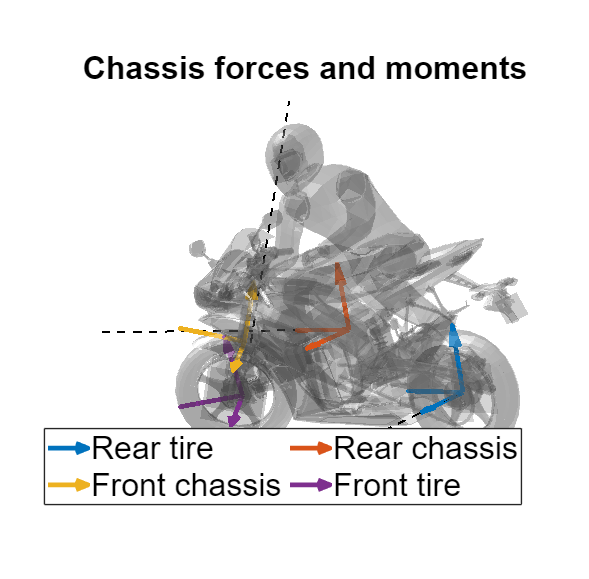

cla;
q = [-40,-15,1,30];
mf = bigSportsFigure();
setColor(mf,n0,n0,n0,n0);
setAlpha(mf,0.25,0.25,0.25,0.25);
setPose(mf,q);
delete(leg);

d = tr*Ryaw(:,3) + (rr - tr).*Rcamber(:,3);
T = rigidtform3d(Rcamber,d);
LMy = plotDoFLine(axe,T,yhat,0.7);
hpitchr = plotFrame(axe,T,mblue);

d = d + (h - rr).*Rpitch(:,3) + b.*Rpitch(:,1);
T = rigidtform3d(Rpitch,d);
LMx = plotDoFLine(axe,T,xhat,1.5);
hb = plotFrame(axe,T,morange);

d = d - h.*Rpitch(:,3) + a.*Rcaster(:,1);
d = d + e.*Rsteer(:,1) + f.*Rsteer(:,3);
T = rigidtform3d(Rsteer,d);
LMz = plotDoFLine(axe,rigidtform3d(Rsteer,d - e.*Rsteer(:,1)),zhat,1.2);
hsteer = plotFrame(axe,T,myellow);

d = d  - e.*Rsteer(:,1) - f.*Rsteer(:,3) - lz.*Rsteer(:,3);
T = rigidtform3d(Rsteer*roty(caster),d);
hpitchf = plotFrame(axe,T,mpurple);

axe = gca;
view(axe,180,15);
axis(axe,'equal');
axis(axe,'tight');
box(axe,'on');
light(axe);
view(180,0);
xticks(axe,[]);
yticks(axe,[]);
zticks(axe,[]);
axe.XColor = 'w';
axe.YColor = 'w';
axe.ZColor = 'w';

names = {
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    'Rear tire';
    '';
    '';
    '';
    'Rear chassis';
    '';
    '';
    '';
    'Front chassis';
    '';
    '';
    'Front tire'
    };

title(axe,"Chassis forces and moments","FontSize",24);

leg = legend(axe,names{:}, ...
    'FontSize',24, ...
    'Orientation','horizontal', ...
    'NumColumns',2, ...
    'Location','South');

print(fig,'chassis_forces','-dpng','-r300');

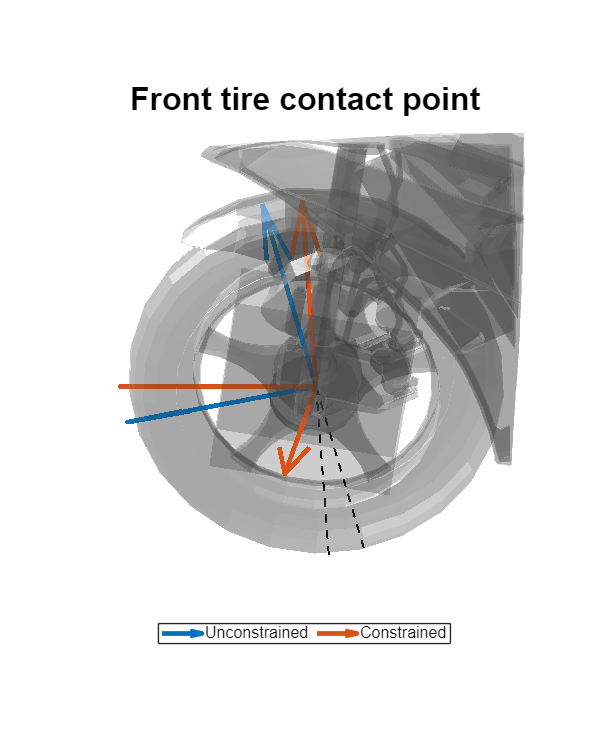

cla;
q = [-40,-15,1,35];
mf = bigSportsFigure();
setColor(mf,n0,n0,n0,n0);
setAlpha(mf,0.25,0.25,0.25,0.25);
setPose(mf,q);
delete(leg);

Ra = Rsteer*roty(caster);
ra = -rf.*Ra(:,3);

nz = Ryaw(:,3);
ny = Rpitchf(:,2);
nx = cross(ny,nz)./norm(cross(ny,nz));
rb = rf.*cross(ny,nx);
reach = acosd(ra.'*rb./(norm(ra)*norm(rb)));

Rb = Ra*roty(reach).';
d = tr*Ryaw(:,3) + (rr - tr).*Rcamber(:,3);
d = d + (h - rr).*Rpitch(:,3) + b.*Rpitch(:,1);
d = d - h.*Rpitch(:,3) + a.*Rcaster(:,1);
d = d - lz.*Rsteer(:,3) + lx.*Rsteer(:,1);

axe = gca;
view(axe,180,15);
axis(axe,'equal');
axis(axe,'tight');
box(axe,'on');
light(axe);
view(180,0);
xticks(axe,[]);
yticks(axe,[]);
zticks(axe,[]);
axe.XColor = 'w';
axe.YColor = 'w';
axe.ZColor = 'w';

Ta = rigidtform3d(Ra,d);
Tb = rigidtform3d(Rb,d);
la = plotDoFLine(axe,Ta,-zhat,rf);
lb = plotDoFLine(axe,Tb,-zhat,rf);
ha = plotFrame(axe,Ta,mblue);
hb = plotFrame(axe,Tb,morange);

xlim(axe,[0.75,1.35]);
zlim(axe,[-0.01,0.6])

title(axe,'Front tire contact point','FontSize',24);

names = {
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    '';
    'Unconstrained';
    '';
    '';
    '';
    'Constrained'
    };

leg = legend(axe,names{:}, ...
    'Fontsize',12, ...
    'Location','South', ...
    'Orientation','horizontal');

fig.Position = [0,0,640,1.25*640];
print(fig,'front_tire_holonomic_constraint','-dpng','-r300');

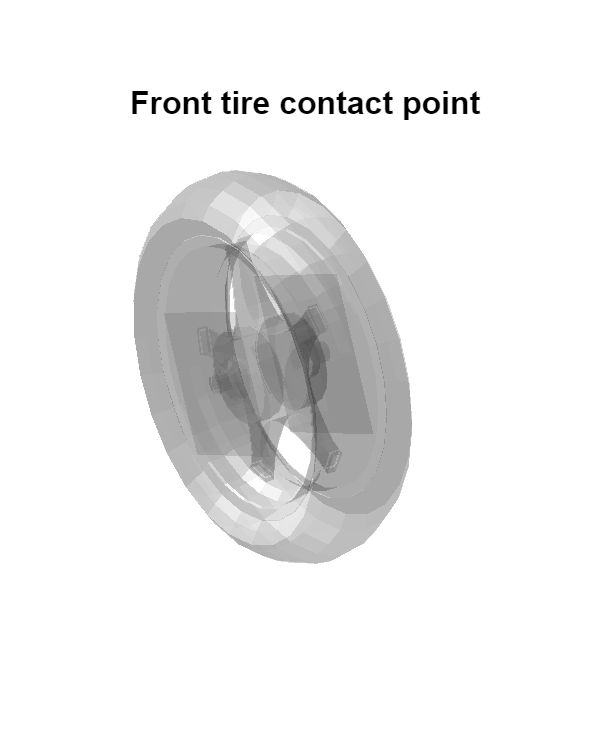

cla;
q = [-60,-15,1,35];
mf = bigSportsFigure();
setColor(mf,n0,n0,n0,n0);
setAlpha(mf,0.25,0,0,0);
setPose(mf,q);
delete(leg);
view(axe,180,15);
axis(axe,'equal');
axis(axe,'tight');
box(axe,'on');
light(axe);
view(180,0);
xticks(axe,[]);
yticks(axe,[]);
zticks(axe,[]);
axe.XColor = 'w';
axe.YColor = 'w';
axe.ZColor = 'w';
xlim(axe,[-0.3,0.3]);
zlim(axe,[0,0.6]);

function setColor(h,rt,rc,fc,ft)
    h.RearTire.Patch.FaceColor = rt;
    h.SwingArm.Patch.FaceColor = rc;
    h.Base.Patch.FaceColor = rc;
    h.Body.Patch.FaceColor = rc;
    h.Handlebars.Patch.FaceColor = fc;
    h.ForkTop.Patch.FaceColor = fc;
    h.FrontFender.Patch.FaceColor = fc;
    h.Fork.Patch.FaceColor = fc;
    h.FrontTire.Patch.FaceColor = ft;
    h.LeftLeg.Patch.FaceColor = rc;
    h.RightLeg.Patch.FaceColor = rc;
    h.Driver.Patch.FaceColor = rc;
    h.LeftArm.Patch.FaceColor = rc;
    h.RightArm.Patch.FaceColor = rc;
end

function setAlpha(h,rt,rc,fc,ft)
    h.RearTire.Patch.FaceAlpha = rt;
    h.SwingArm.Patch.FaceAlpha = rc;
    h.Base.Patch.FaceAlpha = rc;
    h.Body.Patch.FaceAlpha = rc;
    h.Handlebars.Patch.FaceAlpha = fc;
    h.ForkTop.Patch.FaceAlpha = fc;
    h.FrontFender.Patch.FaceAlpha = fc;
    h.Fork.Patch.FaceAlpha = fc;
    h.FrontTire.Patch.FaceAlpha = ft;
    h.LeftLeg.Patch.FaceAlpha = rc;
    h.RightLeg.Patch.FaceAlpha = rc;
    h.Driver.Patch.FaceAlpha = rc;
    h.LeftArm.Patch.FaceAlpha = rc;
    h.RightArm.Patch.FaceAlpha = rc;
end

function ax = plotAxis(axe,idx,pose,scale,color,style)
    x = pose.Translation(1);
    y = pose.Translation(2);
    z = pose.Translation(3);
    u = scale.*pose.R(1,idx);
    v = scale.*pose.R(2,idx);
    w = scale.*pose.R(3,idx);

    hold(axe,'on');

    ax = quiver3(axe,x,y,z,u,v,w,'filled', ...
        'AutoScale','off', ...
        'MaxHeadSize',1, ...
        'Color',color, ...
        'LineWidth',3.5, ...
        'LineStyle',style ...
        );

    hold(axe,'off');
    uistack(ax,'top');
end

function h = plotFrame(axe,pose,color,style)
    arguments
        axe 
        pose 
        color 
        style = '-'
    end
    scale = 0.3;
    h.x = plotAxis(axe,1,pose,scale,color,style);
    h.y = plotAxis(axe,2,pose,scale,color,style);
    h.z = plotAxis(axe,3,pose,scale,color,style);
end

function h = plotDoFLine(axe,pose,dir,len)
    arguments
        axe
        pose
        dir
        len = 1
    end
    p0 = len.*[
        0,0,0;
        dir
        ];

    p = transformPointsForward(pose,p0);
    hold(axe,'on');
    h = plot3(axe,p(:,1),p(:,2),p(:,3),'k--','LineWidth',1.5);
    hold(axe,'off');

    % uistack(h,'bottom');
end

% function removeFrames(axe)
%     n = numel(axe.Children);
%     idx = true(n,1);
%     type = 'matlab.graphics.chart.primitive.Quiver';
%     for k = 1:n
%         if isa(axe.Children(k),type)
%             idx(k) = false;
%         end
%     end
%     delete(axe.Children(~idx));
% end